# 10 Least-Squares Problems 

#### Example

The following table contains the homework and final grades of 30 students.

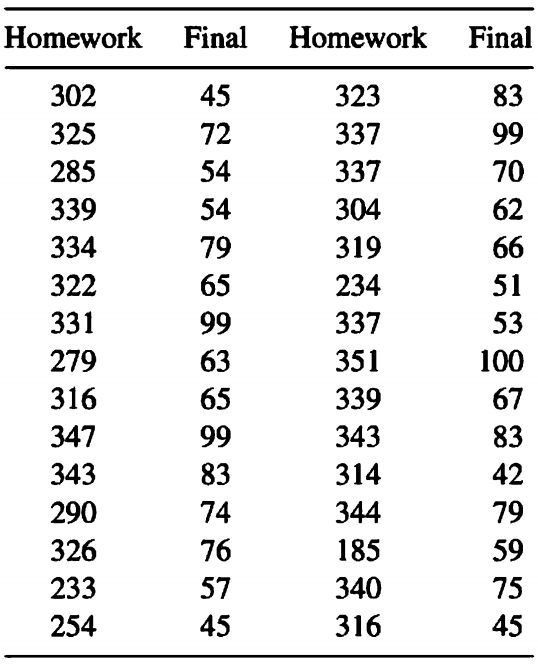

Based on these data, what is the homework grade that gives a predition of A+ (95%) in the final?

HW  = [302 325 285 339 334 322 331 279 316 347 343 290 326 233 254 ... 
       323 337 337 304 319 234 337 351 339 343 314 344 185 340 316   ];
FIN = [45 72 54 54 79 65 99 63 65 99 83 74 76 57 45 83 99 70 62 66 51 53 ... 
       100 67 83 42 79 59 75 45];

   
   sumT = sum(HW);
   sumT2 = sum(HW.^2);
   m = 30;
   sumY = sum(FIN);
   sumTY = sum(HW.*FIN);
   
   A = [sumT2 sumT;sumT m];
   b = [sumTY;sumY];
   
   sol = A\b;
   alpha = sol(1);
   beta = sol(2);
   x = linspace(min(HW),max(HW)+100);
   reHW = (95-beta)/alpha

reHW = 428.9388

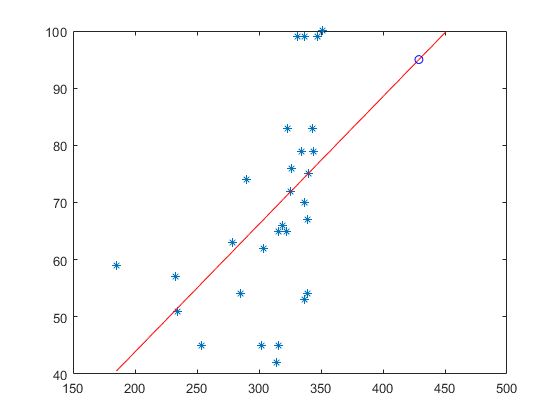

   plot(HW,FIN, '*', x, alpha*x+beta, 'r',reHW,95,'bo')

   polyfit(HW,FIN, 1)

ans =     0.2233   -0.8028


## 10.2 LINEAR LEAST-SQUARES PROBLEMS   

- A linear least-squares problem is 


$$\min_{x\in \mathbb{R}^n} f(x)=(1/2)||Jx-y||^2.$$


- The gradient is $\nabla f = J^T(Jx-y)$

- The Hessian is $\nabla^2 f =  J^TJ$

- The function $f$ is convex (why?)

- If $x^*$ is such that $\nabla f(x^*)=0$, then $x^*$ is a global minimizer of $f$ and we have the normal equations  $J^TJx = J^Ty$

- We assum that $m\ge n$ where $m$ is the number of observations. That is $m$ is the numebr of rows in $J$.

- We assume also that $J$ has a full (column) rank.

- We solve Linear Least Square by QR method or by SVD method

Let $J=QR$

   clearvars
   rng('default');
   J = randi([-3,3],10,3);
   [Q, R]= qr(J)

Q =    -0.2520    0.3951   -0.1499   -0.6887   -0.1519    0.1205    0.0589    0.2068   -0.4304   -0.1205
   -0.3780   -0.2657    0.3205    0.1394   -0.1293    0.4665    0.2687   -0.3321   -0.1733   -0.4665
    0.3780   -0.5927   -0.4034   -0.2417   -0.3351    0.0260   -0.1896   -0.2624   -0.2573   -0.0260
   -0.3780    0.1635   -0.6253    0.5757   -0.1705   -0.0079   -0.0833    0.0515   -0.2630    0.0079
   -0.1260   -0.2316   -0.2959   -0.1286    0.8894    0.0775   -0.0026   -0.0711   -0.1352   -0.0775
    0.3780    0.2657   -0.1410    0.0808    0.0501    0.8395   -0.1014    0.0437    0.1220    0.1605
    0.2520    0.0341   -0.2574    0.0171   -0.0203   -0.0734    0.9254   -0.0199    0.0292    0.0734
         0   -0.4292    0.0483    0.0841   -0.0404    0.1298    0.0671    0.8751   -0.0288   -0.1298
   -0.3780   -0.1226   -0.3538   -0.2818   -0.1438    0.0915    0.0007   -0.0219    0.7744   -0.0915
   -0.3780   -0.2657    0.1410   -0.0808   -0.0501    0.1605    0.1014   -0.0437   -0.1

R =    -7.9373   -3.0237    2.0158
         0   -6.9898    1.7032
         0         0   -5.5710
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


#### NONLINEAR LEAST SQAURES

**Example**

Let's study the effect  of a drug on a patient. So we draw blood samples at certain times $t_i$ after the patient takes a dose, and measure the concentration, $y_i$ of the medication in each sample. We experimentaly found that the following function gives a good prediction of the concentration at a time $t$


$$\phi(x;t) = x_1 + x_2 t + x_3 t^2 + x_4 e^{-x_5 t}$$


where $x=(x_1,x_2,x_3,x_4,x_5)$ is a five-dimensional parameter vector that we need to find in order for the model to fit our data.

- We need to solve  $\min_{x\in \mathbb{R}^5} f(x)=(1/2) \sum_{i=1}^m\left[\phi(x;t_i) - y_i\right]^2.$

- We define $r_i(x) = \phi(x;t_i) - y_i$; therefore $f(x)=(1/2) \sum_{i=1}^mr_i^2(x).$

#### 10.3 ALGORITHMS FOR NONLINEAR LEAST-SQUARES PROBLEMS

In general, least squares problems we minimize $f$ where $f$ has the form


$$f(x)=(1/2) \sum_{i=1}^mr_i^2(x).$$


- $r_i$ are called the *residual*.

- We now define the residual vector 


$$r(x) =\left[\begin{array}{l}r_1(x) \\ r_2(x) \\ \vdots \\r_m(x) \end{array}\right]$$


- $r:\mathbb{R}^n\to \mathbb{R}^m$ and $f(x)=(1/2)\|r(x)\|^2$

- $\nabla r(x) =J(x) = \left[\nabla r_1(x) ^T, \nabla r_2(x) ^T,\cdots, \nabla r_m(x) ^T \right]^T= \left[\begin{array}{l}\nabla r_1(x)^T \\ \nabla r_2(x) ^T \\ \vdots \\ \nabla r_m(x)^T \end{array}\right]$ (Jacobian)

- So, we have the gradient of $f$


$$\nabla f(x)= \sum_{i=1}^m \nabla r_i(x) r_i(x) = J(x)^T r(x)$$


- The hessian matrix is


$$\nabla^2 f(x) =\sum_{i=1}^m \nabla r_i(x) \nabla r_i(x)^T + \sum_{i=1}^m \nabla^2 r_i(x) r_i(x)= J(x)^TJ(x) + \sum_{i=1}^m \nabla^2 r_i(x) r_i(x)$$


- Most algorithms for nonlinear least-squares exploit these structural properties of the Hessian.

#### THE GAUSS–NEWTON METHOD

- It is one the simplest method that exploits the stucture of the gradient and the Hessian matrix.

- It line search with modified Newton direction

- We find the GAUSS-NEWTON direction $p^{GN}$ by solving the equations


$$J_k^TJ_k p_k^{GN} = - J_k^T r_k$$


Advantages 

- Calculating the derivative is cheap. We do not need to find the second derivative of $r$.

- The term $J^T J$, in some applications, may dominate the second term (at least close to the solution $x^\ast $ ), so that $J^T_ k J_k$ is a close approximation to $\nabla ^ 2f_k$ and the convergence rate of Gauss–Newton is similar to that of Newton’s method

- Whenever $J_k$ has full rank and the gradient $\nabla f_k$ is nonzero, the direction $p^{GN}_ k$ is a descent direction for $f$

- These equations are similar to the normal equations  $J^TJx = J^Ty$ in our discussion of LLS. So, we can see $p^{GN}$ as a solution of the linear least squares 


$$\min_{p\in \mathbb{R}^n} (1/2)||J_kp+r_k||^2.$$


      Hence, we can find the search direction by applying linear least-squares algorithms to this subproblem (QR or SVD)

Implementations of the Gauss–Newton method usually perform a line search in the direction $p^{GN}_ k$ , requiring the step length $\alpha _k$ to satisfy conditions like those discussed in Chapter 3, such as the Armijo and Wolfe conditions

#### CONVERGENCE OF THE GAUSS–NEWTON METHOD

**Theorem: **Suppose each $r_i$ is Lipschitz continuously differentiable in a neighborhood $\mathcal{N}$ of $\{x | f(x) \le  f(x_0)\}$ and the Jacobians $J(x)$ satisfy $||J(x)z||\ge \gamma ||z||$ for all $x\in\mathcal{N}$. Then the Gauss-Newton method, with $\alpha _k$ that satisfies the Wolfe conditions, has 


$$\lim_{k\to \infty } J^T_k r_k = 0$$


**Remarks:**

- This global convergence result is under the assumption that the Jacobians $J(x)$ have their singular values uniformly bounded away from zero in the region of interest; the lower level set $\{x | f(x) \le  f(x_0)\}$

- This condition exposes a weakness of this method which arises when $J$ is rank deficient.

#### THE LEVENBERG–MARQUARDT METHOD

It is a trust-regoin Newton method. The Levenberg–Marquardt method can be described and analyzed using the trustregion framework

- The subproblem to be solved at each iteration is

$\min_{p\in \mathbb{R}^n} (1/2)||J_kp+r_k||^2, \qquad \text{subject to }\|p\|\leq \Delta_k$, where $\Delta_k>0$.

Recall the following theorem from chapter 4.

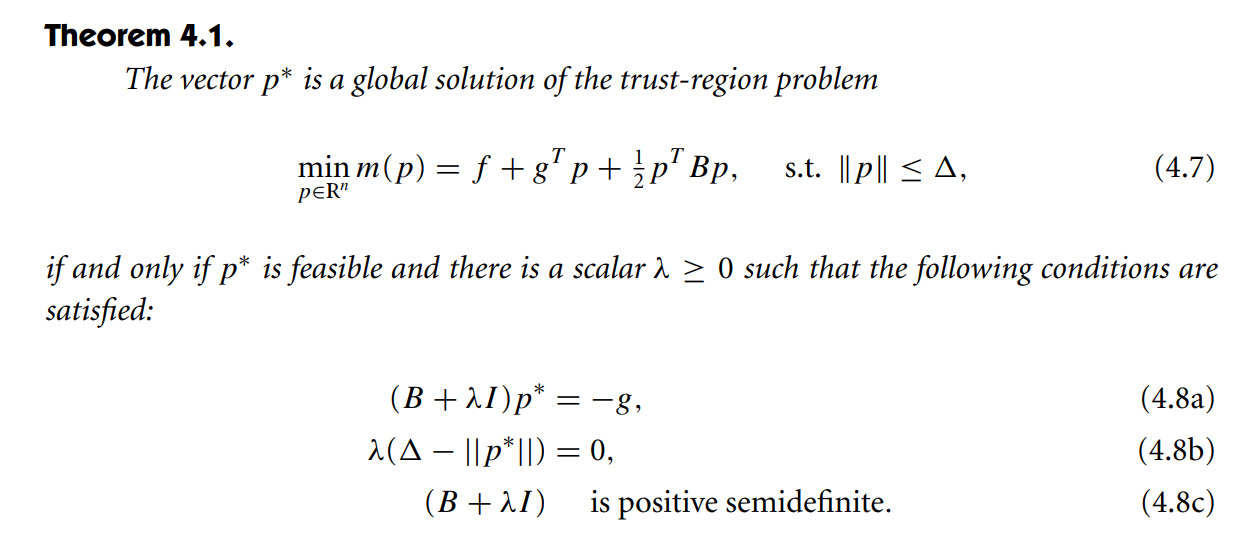

Here the model function is 


$$m(p) = {1\over 2}\|r\|^2 + p^tJ^Tr+ {1\over 2}p^TJ^TJp.$$


So, by Theorem 4.1, $p^*$ is a global solution iff

                        $\left(J^TJ + \lambda I\right)p^* = - J^tr$         --- (*)

                        
$$\lambda\left(\Delta - \|p^*\|\right)=0$$
 

(*) is the normal equations of the LLS 

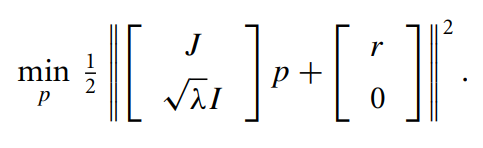

#### CONVERGENCE OF THE LEVENBERG–MARQUARDT METHOD

**Theorem **Suppose $\mathcal{L}=\{x | f (x) \le  f (x_0)\}$ is bounded and each $r_i$ is Lipschitz continuously differentiable in a neighborhood $\mathcal{N}$ of $\mathcal{L}$. Assume for each $k$, the approximation solution $p_k$ of the Levenberg Marquardt method satisfies the inequality 


$$m_k(0) - m_k(p_k) \ge  c_1\|J^T_k r_k\| \min\left(∆_k, \frac{\|J^T_k r_k\|}{\|J^T_k J_k\|}\right)$$


for some constant $c_1>0$, and $||pk||\le \gamma ∆k$ for some $\gamma >1$. Then 


$$\lim_{k\to \infty } J^T_k r_k = 0$$
